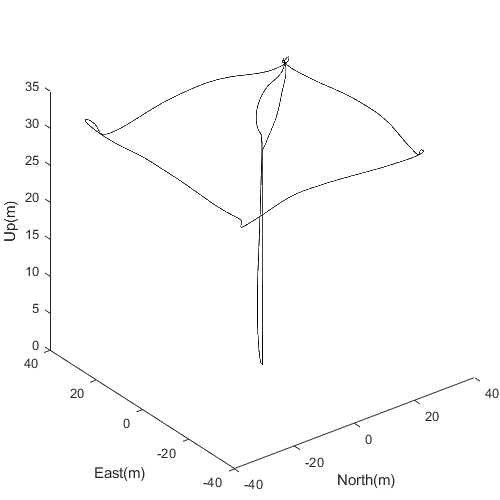

figure
plot3(out.pos.Data(:,1),out.pos.Data(:,2),out.alt.Data(:),"Color",'black')
xlabel('North(m)')
ylabel('East(m)')
zlabel('Up(m)')
set(gca,'LooseInset',get(gca,'TightInset'));
set(gcf, 'Position',  [100, 100, 500, 500])

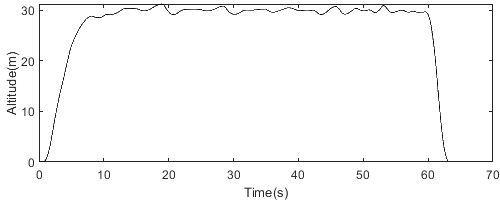


figure
plot(out.alt.Time,out.alt.Data(:),'Color', 'black')
xlabel('Time(s)')
ylabel('Altitude(m)')
set(gca,'LooseInset',get(gca,'TightInset'));
set(gcf, 'Position',  [100, 100, 500, 200])

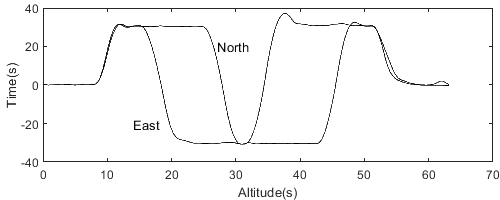


figure
plot(out.alt.Time,out.pos.Data(:,1),'Color', 'black')
hold on
plot(out.alt.Time,out.pos.Data(:,2),'Color', 'black')
text(27, 20, "North")
text(14, -20, "East")
xlabel('Altitude(s)')
ylabel('Time(s)')
set(gca,'LooseInset',get(gca,'TightInset'));
set(gcf, 'Position',  [100, 100, 500, 200])

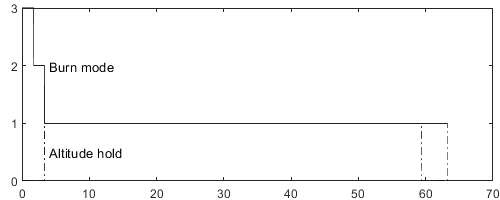


figure
plot(out.machine_states.Time,out.machine_states.Data(:,1),'Color', 'black')
hold on
plot(out.machine_states.Time,out.machine_states.Data(:,2),'-.','Color', 'black')
hold off
text(4, 2, 'Burn mode')
text(4, 0.5, 'Altitude hold')
set(gca,'LooseInset',get(gca,'TightInset'));
set(gcf, 'Position',  [100, 100, 500, 200])

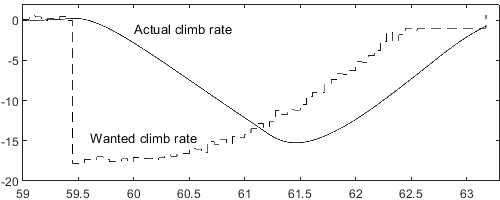


figure
plot(out.climb_rate.Time,out.climb_rate.Data(:,1),'--','Color', 'black')
hold on
plot(out.climb_rate.Time,out.climb_rate.Data(:,2),'Color', 'black')
text(60, -1, 'Actual climb rate')
text(59.6, -14.5, 'Wanted climb rate')
xlim([59 63.3])
ylim([-20 2])
set(gca,'LooseInset',get(gca,'TightInset'));
set(gcf, 'Position',  [100, 100, 500, 200])